**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Authors: P.Ozga 

dataset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

dataset from: by `Mustanger from kaggle link:`

https://www.kaggle.com/code/eisgandar/red-wine-quality-eda-classification/input

### Toolbox: Statistics and Machine Learning & Deep Learning

## 1. Data loading and Display

close all; 
fpath = fullfile(pwd,'wine-quality_bufor.csv');                % File path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file
firstFive = head(fname, 5);                                      % Display first 5 rows
verticalView = array2table(firstFive.Variables', ...
    'VariableNames', strcat("Sample ", string(1:5)), ...
    'RowNames', fname.Properties.VariableNames);
disp(verticalView);

                            Sample 1    Sample 2    Sample 3    Sample 4    Sample 5
                            ________    ________    ________    ________    ________

    fixed acidity                7         6.3          8.1         7.2         8.1 
    volatile acidity          0.27         0.3         0.28        0.23        0.28 
    citric acid               0.36        0.34          0.4        0.32         0.4 
    residual sugar            20.7         1.6          6.9         8.5         6.9 
    chlorides                0.045       0.049         0.05       0.058        0.05 
    free sulfur dioxide         45          14           30          47          30 
    total sulfur dioxide      

Table 1.1 Wine characteristics- first 5 samples

% DEBUG NAMES
if isempty(fname.Properties.VariableNames)
    disp('Warning: The dataset lacks variable names!');
end

## **2. Data Verification**

nonNumericCols = varfun(@isnumeric, fname);                 % Check each columns
nonNumericColsNames = fname.Properties.VariableNames(~all(nonNumericCols{:, :}, 1));
if ~isempty(nonNumericColsNames)                            %is numeric or no-numeric?
    disp('Database is non-numeric.');
    disp(nonNumericColsNames);
else
    disp('Each columns is numeric.');
    numRows = height(fname);                                % or: size(fname, 1);
end

Each columns is numeric.


## 3. Dataset Statistics Calculation

numericCols = varfun(@isnumeric, fname, 'OutputFormat', 'uniform');
numericData = fname(:, numericCols);
dataArray = numericData{:,:};
countVals = sum(~ismissing(dataArray))';                    % Compute statistic
minVals   = min(dataArray)';
p25Vals   = prctile(dataArray, 25)';
p50Vals   = prctile(dataArray, 50)';
p75Vals   = prctile(dataArray, 75)';
meanVals  = mean(dataArray)';
stdVals   = std(dataArray)';
maxVals   = max(dataArray)';
summaryVertical = table(countVals, minVals, p25Vals, p50Vals, p75Vals, meanVals, stdVals, maxVals, ...
    'VariableNames', {'Count','Min','P25%','P50%','P75%','Mean','Std','Max'}, ...
    'RowNames', numericData.Properties.VariableNames);
summaryVertical = round(summaryVertical, 3); % X.3f
disp(summaryVertical);

                            Count     Min     P25%     P50%     P75%      Mean      Std       Max 
                            _____    _____    _____    _____    _____    ______    ______    _____

    fixed acidity           4687       3.8      6.3      6.8      7.3     6.874     0.901     11.8
    volatile acidity        4687      0.08     0.22     0.27     0.34     0.293     0.118      1.1
    citric acid             4687         0     0.27     0.32     0.38      0.33     0.122     1.66
    residual sugar          4687       0.6      1.7      4.7      9.2      6.06     4.943     65.8
    chlorides               4687     0.012    0.

Table 3.1 Count values Min, Max, Mean

## 4. Sample Selection for Each Quality Class

validClasses = 4:8;                                                 % Define classes
samples = {};                                                       % initial empty list of samples
samples = {};
sampleCounter = 1;
for i = 1:length(validClasses)
    quality_class = validClasses(i);
    sample = fname(fname.quality == quality_class, :);
    if ~isempty(sample)
        samples{sampleCounter} = sample(1, :); % Take first sample of the class
        sampleCounter = sampleCounter + 1;
    else
        warning("No sample found for quality class %d", quality_class);
    end
end

%DEBUG IF QUALITY NOT FOUND
if ~ismember('quality', fname.Properties.VariableNames)
    error('Quality column not found in the dataset');
end

samples_table = vertcat(samples{:});                                % sum samples and create horizontal table
samples_transposed = array2table(samples_table.Variables', ...
    'VariableNames', strcat("Class ", string(validClasses)), ...  
    'RowNames', samples_table.Properties.VariableNames);
disp(samples_transposed);

                            Class 4    Class 5    Class 6    Class 7    Class 8
                            _______    _______    _______    _______    _______

    fixed acidity              6.2        7.9          7        6.6        6.2 
    volatile acidity          0.45       0.18       0.27       0.16       0.66 
    citric acid               0.26       0.37       0.36        0.4       0.48 
    residual sugar             4.4        1.2       20.7        1.5        1.2 
    chlorides                0.063       0.04      0.045      0.044      0.029 
    free sulfur dioxide         63         16         45         48         29 
    total sulfur dioxide       206         75        170        143   

Table 4.1 Sample selection for 7 classes

## 5. Class Distribution

qualityCounts = countcats(categorical(fname.quality));
uniqueClasses = unique(fname.quality);
for i = 1:length(uniqueClasses)
    fprintf('Class %d has %d samples\n', uniqueClasses(i), qualityCounts(i));
end

Class 4 has 732 samples
Class 5 has 1157 samples
Class 6 has 1198 samples
Class 7 has 880 samples
Class 8 has 720 samples


%Features4 = {'alcohol', 'volatile acidity', 'sulphates', 'citric acid'};
%X = fname{:, Features4};  % Only the 4 selected features
X = fname{:,1:end-1};                                                    % for all features
Y = fname{:, 12};

Table 5.1 Class Distribution

## Corelation

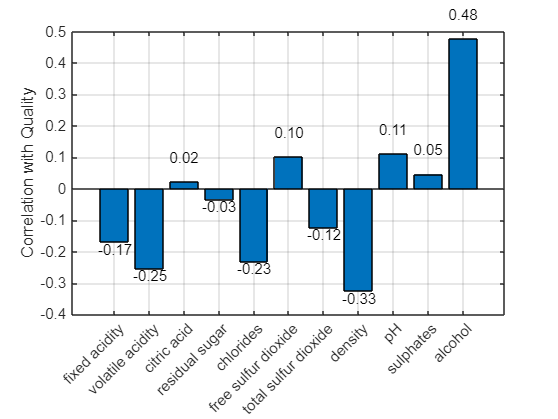

corrMatrix = corr([X Y]);
corrWithQuality = corrMatrix(1:end-1, end);
figure; bar(corrWithQuality);
featureNames = fname.Properties.VariableNames(1:end-1);
xticklabels(featureNames); xtickangle(45);
ylabel('Correlation with Quality'); grid on;
x = 1:length(corrWithQuality);
y = corrWithQuality;
for i = 1:length(x)
    text(x(i), y(i) + sign(y(i))*0.05, sprintf('%.2f', y(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

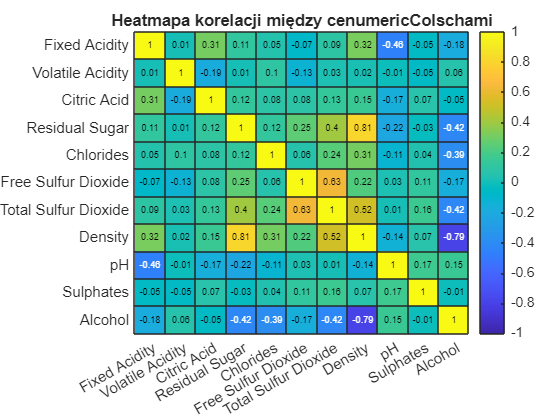

figure;
corrMatrix = corr(X); % korelacja między cechami (bez quality)
heatmap({'Fixed Acidity','Volatile Acidity','Citric Acid','Residual Sugar',...
         'Chlorides','Free Sulfur Dioxide','Total Sulfur Dioxide','Density',...
         'pH','Sulphates','Alcohol'}, ...
        {'Fixed Acidity','Volatile Acidity','Citric Acid','Residual Sugar',...
         'Chlorides','Free Sulfur Dioxide','Total Sulfur Dioxide','Density',...
         'pH','Sulphates','Alcohol'}, ...
         round(corrMatrix,2), ...
         'Colormap',parula, ...
         'ColorLimits',[-1 1], ...
         'MissingDataColor',[1 1 1]);
title('Heatmapa korelacji między cenumericColschami');

## 6. Normalization input

X = normalize(X, 'range'); 

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## 7. Labels Encoding (One-hot Encoding)

Y_cat = categorical(Y);
Y_encoded = dummyvar(Y_cat);                                            % One-hot encoding

# Training and Testing Neural Network

## 8. Data Splitting

about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

% cv = cvpartition(Y_cat,'Holdout',0.2);                                  % two set
% X_train = X(training(cv),:);
% Y_train = Y_encoded(training(cv),:);
% X_test = X(test(cv), :);
% Y_test = Y_encoded(test(cv), :);
validClasses = unique(Y);
trainIdx = [];
testIdx = [];
holdoutRatio = 0.2; % 20% danych na test

% Stratyfikowany podział
for i = 1:length(validClasses)
    classValue = validClasses(i);
    classIndices = find(Y == classValue);
    
    % Tasujemy indeksy
    classIndices = classIndices(randperm(length(classIndices)));
    
    % Dzielimy na test i trening
    numTest = round(holdoutRatio * length(classIndices));
    
    testIdx = [testIdx; classIndices(1:numTest)];
    trainIdx = [trainIdx; classIndices(numTest+1:end)];
end

% Tworzymy zbiory
X_train = X(trainIdx, :);
Y_train = Y_encoded(trainIdx, :);
X_test  = X(testIdx, :);
Y_test  = Y_encoded(testIdx, :);

tabulate(vec2ind(Y_train')')

  Value    Count   Percent
      1      586     15.63%
      2      926     24.69%
      3      958     25.55%
      4      704     18.77%
      5      576     15.36%


tabulate(vec2ind(Y_test')')

  Value    Count   Percent
      1      146     15.58%
      2      231     24.65%
      3      240     25.61%
      4      176     18.78%
      5      144     15.37%


## 9. Build MLP (Multilayer Perceptron) Network:

X_train_weighted = X_train;

net = patternnet([20, 10]);                                             % Hidden layers
net.trainFcn = 'trainscg';                                              % Scaled conjugate gradient
net.layers{end}.transferFcn = 'softmax';                                % Last layers = output = classification
net.performFcn = 'crossentropy';                                        % Function of cost
Y_train_classes = vec2ind(Y_train')';
numClasses = size(Y_train, 1);
numSamplesPerClasses = histcounts(Y_train_classes, 0.5:1:(numClasses + 0.5));
disp(numSamplesPerClasses);

   586   926   958   704   576     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

classWeights = zeros(size(numSamplesPerClasses));
nonzeroIdx = numSamplesPerClasses > 0;
classWeights(nonzeroIdx) = 1 ./ numSamplesPerClasses(nonzeroIdx);
classWeights = classWeights / max(classWeights);

Train Network

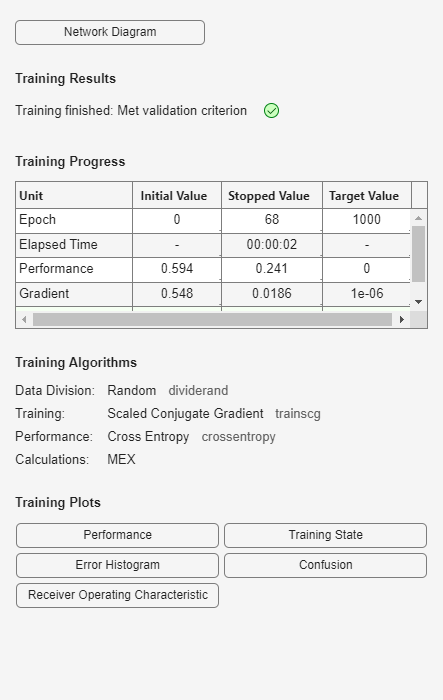

X_train_weighted = X_train_weighted';
Y_train = Y_train';
sampleWeights = classWeights(Y_train_classes)';
net.trainParam.showWindow = true; 
[net, tr] = train(net, X_train_weighted, Y_train,[],[], sampleWeights);                    % Train, add weights

## 10. Prediction and Evaluation

Y_pred = net(X_test');
Y_pred_class = vec2ind(Y_pred);                                         % Change from one-hot to class index
Y_test_class = vec2ind(Y_test');
correct = (Y_pred_class == Y_test_class);  
test_classes = vec2ind(Y_test')';
testWeights = classWeights(test_classes)';
correct = (Y_pred_class' == test_classes);
weightedAccuracy = sum(correct .* testWeights) / sum(testWeights);
fprintf('Weighted Accuracy: %.2f%%\n', weightedAccuracy * 100);

Weighted Accuracy: 42.89%


## 11. Confusion Matrix

cm = confusionmat(Y_test_class, Y_pred_class);
precision = diag(cm)./sum(cm,2) + eps;
recall = diag(cm)./(sum(cm,1)' + eps);
f1 = 2 * (precision .* recall) ./ (precision + recall);                             % F1- score
macroF1 = mean(f1(~isnan(f1)));
% figure(4);
% bar(macroF1);
% xlabel('Macro F1- score');
% ylabel('Macro F1- score');
fprintf('Macro F1-score: %.2f\n', macroF1);

Macro F1-score: 0.43


figure(1);
numClasses = size(Y_encoded, 2); 
Y_test_vec = full(ind2vec(Y_test_class, numClasses));
Y_pred_vec = full(ind2vec(Y_pred_class, numClasses));
plotconfusion(Y_test_vec, Y_pred_vec);
classLabels = {'4','5','6','7','8','F1'};
ax = gca;
ax.XTickLabel = classLabels;
ax.YTickLabel = classLabels;
% figure(2);
% plot(Y_test_class, 'b-o', 'LineWidth', 1.5); hold on;
% plot(Y_pred_class, 'r--s', 'LineWidth', 1.5);
% legend('Real quality', 'Predicted quality', 'Location', 'best');
% xlabel('Sample index');
% ylabel('Quality class');
% classLabels = {'4','5','6','7','8','F1'};
% ax = gca;
% %ax.XTickLabel = classLabels;
% ax.YTickLabel = classLabels;
% grid on;
drawnow;                                                                % debugging while buffering
pause(20);
